# **SYS823 - Modélisation, automatisation de procédés industriels **

# Exemple de contrôle d'un double pendule

Dans cet exemple, nous allons voir comment modéliser et contrôler le mouvement d'un double pendule.

Un double pendule est un pendule avec un autre pendule attaché à son extrémité, est un système physique simple qui présente un comportement dynamique riche avec une forte sensibilité aux conditions initiales. Le double pendule est un exemple de système physique simple qui peut présenter un caractère chaotique (c'est à dire qu'il est très sensible aux conditions initiales)..

Il s'agit donc d'un système qui n'est pas évident à mettre en équation, et qui est surtout très complexe à contrôler. 

**Auteurs : G. Ghazi**

**Révision: **Hiver 2022. 

## 1. Présentation du système

Considérons un pendule à double avec des masses $m_1 = 2$kg et $m_2 = 3$ kg attachées par des fils rigides sans masse de longueurs $l_1 = 3$ m et $l_2 = 2$ m. De même, les angles que font les deux fils avec la verticale sont notés $\theta_1$et $\theta_2$, comme illustré sur la figure ci-dessus.

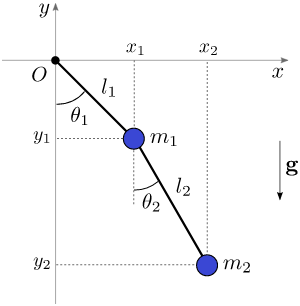

On suppose que les deux masses sont soumisent à la gravité, et que la constante de gravité est $g_0 = 9.81$ m/s$^2$.

La position de chaque masse est donnée par :

- Pour la masse $m_1$ : $[x_1, y_1] = [l_1 \sin(\theta_1), -l_1\cos(\theta_1)]$

- Pour la masse $m_2$ : $[x_2, y_2] = [x+1 + l_2 \sin(\theta_2), -y_1 + l_2\cos(\theta_2)]$

**Note:** on considère que le point d'origine est le point d'attache du pendule. 

## 2. Mise en équation et modèle d'état non-linéaire du double pendule

Nous allons maintenant trouver les équations du mouvement du pendule. Indirectement, cela revient à trouver les équations dynamiques pour les deux masses. Pour cela, nous allons utiliser le Lagrangien, qui s'applique bien pour des systèmes en rotation.

### 2.1. Expression du Lagrangien

Pour utiliser le Lagrangien, il faudra déterminer les énergies potentielle et cinétique du double pendule. Pour cela, nous allons dans un premier temps déclarer et déterminer les positions des deux masses

% Préparation de Matlab
clear ; close all; clc; 
addpath('Program files', 'Simulink models');


% Déclaration des variables symboliques 
syms t g_0 m_1 m_2 l_1 l_2 theta_1(t) theta_2(t) tau

% Position de la masse 1 :
x_1 = l_1*sin(theta_1);
y_1 = -l_1*cos(theta_1);
[x_1, y_1]

$$ans(t) = \left(\begin{array}{cc} l_{1}\,\sin\left(\theta_{1}\left(t\right)\right) & -l_{1}\,\cos\left(\theta_{1}\left(t\right)\right) \end{array}\right)$$

% Position de la masse 2 :
x_2 = x_1 + l_2*sin(theta_2);
y_2 = y_1 - l_2*cos(theta_2);
[x_2, y_2]

$$ans(t) = \left(\begin{array}{cc} l_{1}\,\sin\left(\theta_{1}\left(t\right)\right)+l_{2}\,\sin\left(\theta_{2}\left(t\right)\right) & -l_{1}\,\cos\left(\theta_{1}\left(t\right)\right)-l_{2}\,\cos\left(\theta_{2}\left(t\right)\right) \end{array}\right)$$

% Expression des vitesses pour les deux masses
% Pour la masse 1 :
dx_1 = diff(x_1, t);
dy_1 = diff(y_1, t);

% Pour la masse 2 :
dx_2 = diff(x_2, t);
dy_2 = diff(y_2, t);

Maintenant que nous avons la vitesse, nous pouvons exprimer l'énergie cinétique totale du système :

Ec = simplify(1/2*m_1*(dx_1^2 + dy_1^2) + 1/2*m_2*(dx_2^2 + dy_2^2));

De même, exprimons l'énergie potentielle totale du système :

Ep = simplify(m_1*g_0 * y_1 + m_2*g_0*y_2);

En combinant l'énergie potentielle et l'énergie cinétique, on peut alors trouver le Langrangien du système :

L = simplify(Ec - Ep);

### 2.2. Équation dynamique pour $m_1$

On sait que pour la masse $m_1$, l'équation dynamique est obtenue par :


$$\frac{d}{dt}\left(\frac{\partial L}{\partial \dot{\theta}_1}\right) - \frac{\partial L}{\partial \theta_1} = \tau$$


tmp_a = diff(L, diff(theta_1(t), t));
tmp_a = diff(tmp_a, t);

tmp_b = diff(L, theta_1);

tmp = simplify(tmp_a - tmp_b) == tau;
ddtheta_1 = isolate(tmp, diff(theta_1(t), t, 2))

$$ddtheta\_1 = \begin{array}{l} \frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)=-\frac{l_{1}\,l_{2}\,m_{2}\,\cos\left(\sigma_{1}\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)+l_{1}\,l_{2}\,m_{2}\,\sin\left(\sigma_{1}\right)\,{\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}-\tau +g_{0}\,l_{1}\,m_{1}\,\sin\left(\theta_{1}\left(t\right)\right)+g_{0}\,l_{1}\,m_{2}\,\sin\left(\theta_{1}\left(t\right)\right)}{{l_{1}}^{2}\,m_{1}+{l_{1}}^{2}\,m_{2}}\\ \mathrm{where}\\ \sigma_{1}=\theta_{1}\left(t\right)-\theta_{2}\left(t\right) \end{array}$$

### 2.3. Équation dynamique pour $m_2$

On sait que pour la masse $m_2$, l'équation dynamique est obtenue par :


$$\frac{d}{dt}\left(\frac{\partial L}{\partial \dot{\theta}_2}\right) - \frac{\partial L}{\partial \theta_2} = 0$$


tmp_a = diff(L, diff(theta_2(t), t));
tmp_a = diff(tmp_a, t);

tmp_b = diff(L, theta_2);

tmp = simplify(tmp_a - tmp_b) == 0;
ddtheta_2 = isolate(tmp, diff(theta_2(t), t, 2))

$$ddtheta\_2 = \frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)=-\frac{l_{1}\,\cos\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)-l_{1}\,\sin\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}+g_{0}\,\sin\left(\theta_{2}\left(t\right)\right)}{l_{2}}$$

### 2.3. Équations dynamiques complètes des deux masses

On voit que dans les équations obtenues pour $\ddot{\theta}_1(t)$ et $\ddot{\theta}_2(t)$se croisent. Il faut donc isoler un des deux paramètres, puis le remplacer dans l'équation de l'autre :

eqn_1 = subs(ddtheta_1, diff(theta_2(t), t, 2), rhs(ddtheta_2));
eqn_2 = subs(ddtheta_2, diff(theta_1(t), t, 2), rhs(ddtheta_1));

### 2.4. Modèle d'état du double pendule

Maintenant que nous avons les équations dynamiques pour $\ddot{\theta}_1(t)$ et $\ddot{\theta}_2(t)$, nous pouvons concevoir un modèle d'état (fortement non linéaire) de notre double pendule. Pour cela, on pose le vecteur d'état $\bf{x}$$= [x_1, x_2, x_3, x_4]'$, où:

- $x_1(t) = \theta_1(t)$ : la position angulaire du pendule #1 ;

- $x_2(t) = \dot{\theta}_1(t)$ : la vitesse angulaire du pendule #1 ;

- $x_3(t) = \theta_2(t)$ : la position angulaire du pendule #2 ;

- $x_4(t) = \dot{\theta}_2(t)$ : la vitesse angulaire du pendule #2.

De même, on pose comme commande $u=\tau$, le couple sur le pendule #1.

On a donc le modèle d'état suivant :

% Déclaration des variables d'état en symbolique
syms x_1 x_2 x_3 x_4 u

% Pour la masse m_1 :
f(1, 1) = x_2;
f(2, 1) = subs(rhs(eqn_1), {theta_1(t), theta_2(t), diff(theta_1(t), t), diff(theta_2(t), t), tau}, ...
    {x_1, x_3, x_2, x_4, u});

% Pour la masse m_2 :
f(3, 1) = x_4;
f(4, 1) = subs(rhs(eqn_2), {theta_1(t), theta_2(t), diff(theta_1(t), t), diff(theta_2(t), t), tau}, ...
    {x_1, x_3, x_2, x_4, u});

Ou encore sous forme numérique

% f = subs(f, {m_1, m_2, l_1, l_2, g_0}, {1, 1, 2, 2, 9.81});
% pt_eq = vpasolve(subs(f == 0, u, 0), [x_1, x_2, x_3, x_4]);
% vpa([pt_eq.x_1, pt_eq.x_2, pt_eq.x_3, pt_eq.x_4], 4)

Il est intéressant de voir que Matlab ne trouve qu'un point d'équillibre au double pendule... et pourtant il y en a 4 ! En fait, ce qu'il se passe, c'est que le système est probablement trop complexe pour Matlab qui ne trouve pas toute les solutions de façon évidente. Autre possibilité, pour résoudre l'équation $\bf{f} = 0$, Matlab utilise une approximation numérique avec la fonction "vpa". Dans ce cas, on peut avoir des zéros numériques de l'ordre de $10^{-16}$, mais Matlab ne considère pas que ces variables sont nulles. Il faut donc utiliser un plan de phase, ou le bon sens pour voir que :

% vpa(subs(f, {x_1, x_2, x_3, x_4, u}, {pi, 0, 0, 0, 0}))
% vpa(subs(f, {x_1, x_2, x_3, x_4, u}, {pi, 0, pi, 0, 0}))
% vpa(subs(f, {x_1, x_2, x_3, x_4, u}, {0, 0, pi, 0, 0}))

sont aussi des points d'équilibre. Cependant, seule la position (0,0,0,0) est en revanche stable. 

## 3. Modèle Simulink du double pendule

Nous allons maintenant créer le modèle Simulink de notre pendule, pour préparer le contrôle. Pour cela, nous allons utiliser les équations obtenues dans la section 2.5. 

Notez que le modèle d'état nous permettra de réaliser le contrôle par la suite.

On obtient donc le schéma Simulink suivant :

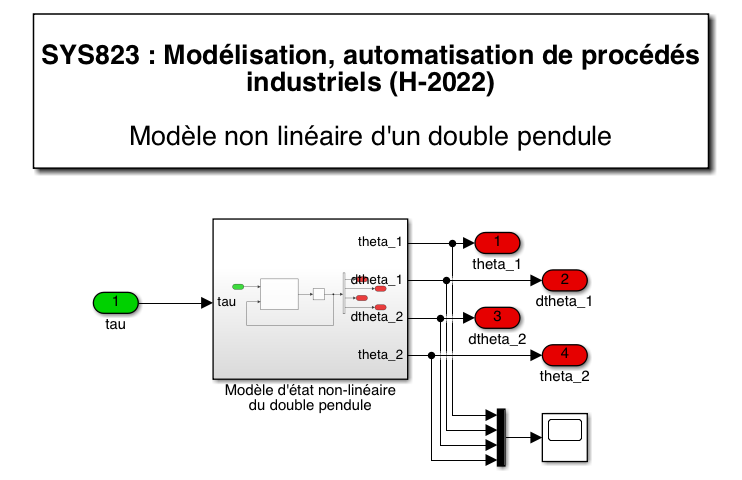

où le bloc "Modéle d'état non-linéaire du double pendule" contient les équations développées dans la section 2.4.

Roulons une simulation pour annalyser le comportement de notre pendule autour d'un point d'équilibre; par exemple, le point d'équilibre $(\pi, 0, \pi, 0)$ qui correspond à la position haute du double pendule (les deux pendules vers le haut).

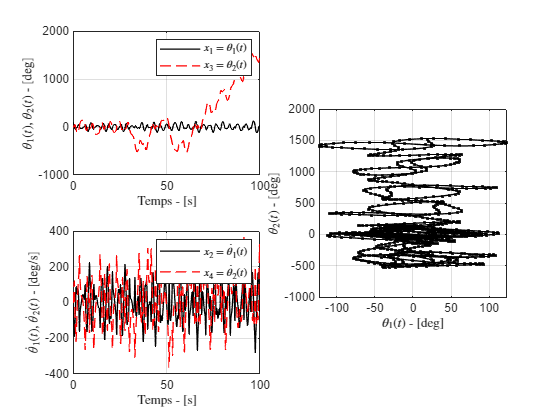

% Définition du vecteur d'état initial (i.e., x[t=0])
x_0 = [90, 0, 0, 0]*pi/180;

% On utilise le modèle Simulink pour simuler le comportement du double
% pendule
y_out = sim('Modele_pendule_a.slx', 0:0.1:100);

% On affiche les trajectoires/vitesses des masses du pendule
figure(1); 
subplot(2, 2, 1); grid on; hold on; box on;
plot(y_out.tout, (y_out.outputs.signals.values(:, 1)*180/pi), '-k', 'LineWidth', 1); 
plot(y_out.tout, (y_out.outputs.signals.values(:, 3)*180/pi), '--r', 'LineWidth', 1);
xlabel('Temps - [s]', 'Interpreter', 'latex');
ylabel('$\theta_1(t)$, $\theta_2(t)$ - [deg]', 'Interpreter', 'latex');
h = legend('$x_1 = \theta_1(t)$', '$x_3 = \theta_2(t)$');
set(h, 'interpreter', 'latex');

subplot(2, 2, 3); grid on; hold on; box on;
plot(y_out.tout, y_out.outputs.signals.values(:, 2)*180/pi, '-k', 'LineWidth', 1); 
plot(y_out.tout, y_out.outputs.signals.values(:, 4)*180/pi, '--r', 'LineWidth', 1);
xlabel('Temps - [s]', 'Interpreter', 'latex');
ylabel('$\dot{\theta}_1(t)$, $\dot{\theta}_2(t)$ - [deg/s]', 'Interpreter', 'latex');
h = legend('$x_2 = \dot{\theta}_1(t)$', '$x_4 = \dot{\theta}_2(t)$');
set(h, 'interpreter', 'latex');

subplot(2, 2, [2 4]); grid on; hold on; box on;
plot(y_out.outputs.signals.values(:, 1)*180/pi, ...
    y_out.outputs.signals.values(:, 3)*180/pi, '.-k'); 
xlabel('$\theta_1(t)$ - [deg]', 'Interpreter', 'latex');
ylabel('$\theta_2(t)$ - [deg]', 'Interpreter', 'latex');
axis square

On peut aussi animer le pendule avec un script de base en Matlab :

% Animation du pendule pour la condition intiale imposée :
f_animationPendule(y_out.tout, y_out.outputs.signals.values, 0.01);

Le double pendule est un système **chaotique**, car son comportement dépend fortement de la condition initiale, ou de possibles perturbations. C'est un peu comme la météo Montréalaise... qui change très vite en raison de perturbation. C'est pourquoi il n'est pas très évident de modéliser et prédire le comportement des systèmes chaotiques. 

**3. Contrôle du double pendule**

Nous allons maintenant essayer de contrôler le double pendule pour qu'il maintienne la position haute, malgrès la présence de perturbation qui pourrait essayer de le faire tomber. Pour cela, nous allons utiliser les outils de Matlab (pidtool / rltool / LQR) pour concevoir un contrôleur capable de contrôler le système.

Avant toute chose, il nous faut une fonction de transfert. Dans notre cas, nous voulons contrôler la position du deuxième pendule (vers le haut) en contrôlant l'entrée $\tau$ (couple sur le premier pendule). Il nous faut donc trouver le modèle d'état linéaire du double pendule atour du point d'équilibre $(\pi,0,\pi,0)$. Pour cela, on peut linéariser le modèle d'état non-linéaire en utilisant le Jacobien, 

A_sym = [diff(f(1, 1), x_1), diff(f(1, 1), x_2), diff(f(1, 1), x_3), diff(f(1, 1), x_4) ;
         diff(f(2, 1), x_1), diff(f(2, 1), x_2), diff(f(2, 1), x_3), diff(f(2, 1), x_4) 
         diff(f(3, 1), x_1), diff(f(3, 1), x_2), diff(f(3, 1), x_3), diff(f(3, 1), x_4)
         diff(f(4, 1), x_1), diff(f(4, 1), x_2), diff(f(4, 1), x_3), diff(f(4, 1), x_4) ];

B_sym = [diff(f(1, 1), u); diff(f(2, 1), u); diff(f(3, 1), u); diff(f(4, 1), u)];

A = subs(A_sym, {m_1, m_2, l_1, l_2, g_0, x_1, x_2, x_3, x_4, u}, {1, 1, 2, 2, 9.81, pi, 0, pi, 0, 0});
B = subs(B_sym, {m_1, m_2, l_1, l_2, g_0, x_1, x_2, x_3, x_4, u}, {1, 1, 2, 2, 9.81, pi, 0, pi, 0, 0});

A = double(A)

A =          0    1.0000         0         0
    4.9050         0   -2.4525         0
         0         0         0    1.0000
   -4.9050         0    4.9050         0


B = double(B)

B =          0
    0.1250
         0
   -0.1250


C = [0 0 1 0]; 
D = 0;

ou utiliser notre modèle Simulink avec la fonction "linmod" de Matlab.

% Utilisation de linmod pour linéariser le modèle du double pendule
% [A, B, C, D] = linmod('Modele_pendule_a', [pi, 0, pi, 0], 0);

Ces deux techniques donnent exactement le même résultat... sauf que la deuxième est parfois plus pratique.

Regardons les pôles de ce système :

damp(A)

                                                            
   Pole        Damping       Frequency       Time Constant  
                           (rad/TimeUnit)     (TimeUnit)    
                                                            
 -2.89e+00     1.00e+00       2.89e+00          3.46e-01    
 -1.20e+00     1.00e+00       1.20e+00          8.34e-01    
  2.89e+00    -1.00e+00       2.89e+00         -3.46e-01    
  1.20e+00    -1.00e+00       1.20e+00         -8.34e-01    


Il est intéressant de voir que le système possède deux modes (deux paires de pôles complexes-conjugués), et que ces deux modes sont instables (partie réelle positive). On s'y attendait car la position "vers le haut" d'un pendule est instable !! Il nous faudra donc dans un premier temps stabiliser le double pendule à l'aide d'un contrôleur. À cet effet, on peut se poser la question suivante : Notre système est-il commandable ? Vérifions cela :

% Calcul de la matrice de commandabilité
Cmd = ctrb(A, B);

% Rang de la matrice de commandabilité
rank(Cmd)

ans = 4

Le rang est bien de 4, donc le système est complétment commandable !

### 3.1. Conception d'un stabilisateur avec la méthode LQR

Nous allons dans un premier temps concevoir un stabilisateur en utilisant la méthode LQR. Pour cela, nous supposons que les états du pendule sont tous mesurables. 

% Choix des pondérations Q et R
Q = diag([1 10 1 10]); R = 0.1;

% Calcul de la matrice de gain LQR
Kx = lqr(A, B, Q, R)

Kx =    -0.1272  -94.1744 -273.2669 -161.7779


% Par placement de pôle
% poles = [-1.05 + 1i*1.0712, -1.05 - 1i*1.0712, -4, -2];
% Kx = place(A, B, poles)

Vérifiions si notre contrôleur fonctionne bien :

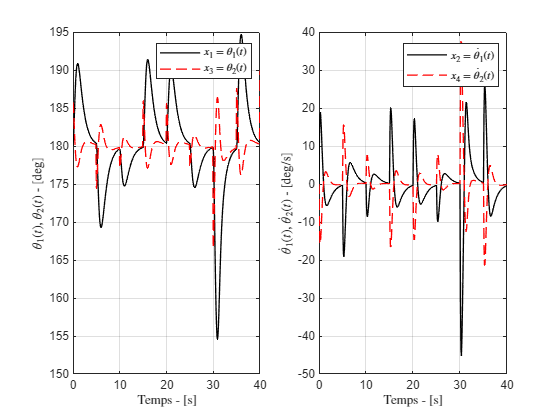

% Définition du vecteur d'état initial (i.e., x[t=0])
x_0 = [pi, 0, pi, 0];

% On utilise le modèle Simulink pour simuler le comportement du double
% pendule
y_out = sim('Modele_pendule_b.slx', 0:0.1:40);

% On affiche les trajectoires/vitesses des masses du pendule
figure(2); 
subplot(1,2,1); grid on; hold on; box on;
plot(y_out.tout, (y_out.outputs.signals.values(:, 1)*180/pi), '-k', 'LineWidth', 1); 
plot(y_out.tout, (y_out.outputs.signals.values(:, 3)*180/pi), '--r', 'LineWidth', 1);
xlabel('Temps - [s]', 'Interpreter', 'latex');
ylabel('$\theta_1(t)$, $\theta_2(t)$ - [deg]', 'Interpreter', 'latex');
h = legend('$x_1 = \theta_1(t)$', '$x_3 = \theta_2(t)$');
set(h, 'interpreter', 'latex');

subplot(1,2,2); grid on; hold on; box on;
plot(y_out.tout, y_out.outputs.signals.values(:, 2)*180/pi, '-k', 'LineWidth', 1); 
plot(y_out.tout, y_out.outputs.signals.values(:, 4)*180/pi, '--r', 'LineWidth', 1);
xlabel('Temps - [s]', 'Interpreter', 'latex');
ylabel('$\dot{\theta}_1(t)$, $\dot{\theta}_2(t)$ - [deg/s]', 'Interpreter', 'latex');
h = legend('$x_2 = \dot{\theta}_1(t)$', '$x_4 = \dot{\theta}_2(t)$');
set(h, 'interpreter', 'latex');

On peut aussi animer le pendule avec un script de base en Matlab :

% Animation du pendule pour la condition intiale imposée :
f_animationPendule(y_out.tout, y_out.outputs.signals.values, 0.01);

### 3.2. Conception d'un PID pour contrôler le mouvement du double pendule

Maintenant que notre double pendule est plus stable sous l'effet du régulateur LQR, nous allons essayer de rajouter un contrôleur PID pour contrôler la position du premier pendule tout en maintenant le deuxième pendule vers le haut. Pour cela, il nous faut calculer le système en boucle fermée, avec le régulateur LQR. On utilise un schéma Simulink pour faire ça :

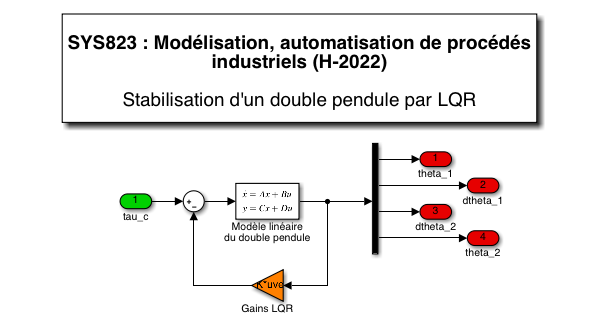

et la fonction "linmod" de Matlab pour obtenir le modèle d'état équivalent.

% Modéle d'état du pendule avec le retour LQR
[A_lqr, B_lqr, C_lqr, D_lqr] = linmod('Modele_pendule_c')

A_lqr =          0    1.0000         0         0
    4.9209   11.7718   31.7059   20.2222
         0         0         0    1.0000
   -4.9209  -11.7718  -29.2534  -20.2222


B_lqr =          0
    0.1250
         0
   -0.1250


C_lqr =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


D_lqr =      0
     0
     0
     0


    On peut maintenant cherche la fonction de transfert entre l'angle $\theta_2(t)$ et l'entrée $\tau_c(t)$:

[num, den] = ss2tf(A_lqr, B_lqr, C_lqr, D_lqr)

num =          0         0    0.1250    0.0000   -0.3066
         0    0.1250    0.0000   -0.3066         0
         0         0   -0.1250   -0.0000    0.0000
         0   -0.1250   -0.0000    0.0000         0


den =     1.0000    8.4504   24.3325   28.8703   12.0685


G = minreal(tf(num(1, :), den));
G = zpk(G)


G =
 
         0.125 (s+1.566) (s-1.566)
  ---------------------------------------
  (s+3.927) (s+2.051) (s+1.409) (s+1.064)
 
Continuous-time zero/pole/gain model.
Model Properties


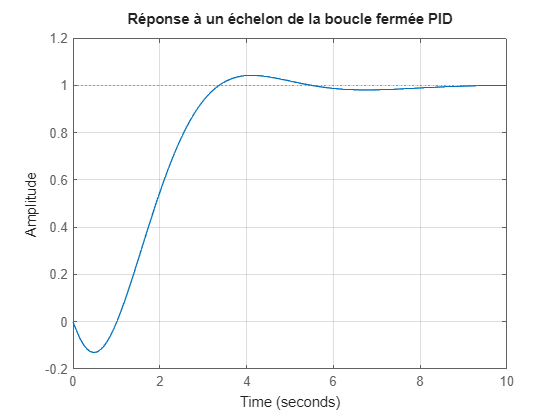


% Utilisation de "pidtool" pour le contrôle de theta_1
% pidtool(G, 'PID');
% pidTunner(G, 'PID');
kp = -27.70; ki = -19.13;
kd = -3.981;
% Fonction de transfert du PID : (kd*s^2 + kp*s + ki)/s
C = pid(kp, ki, kd);

% OU manuellement en tf :
% C = tf([kd kp ki], [1 0]);

% Système en boucle fermée : (C*G)/(1 + C*G)
T = feedback(C*G, 1);

% Tracé de la réponse à un échelon
figure;
step(T)
title('Réponse à un échelon de la boucle fermée PID')
grid on

On peut enfin simuler le comportement du pendule sous l'effet de notre PID :

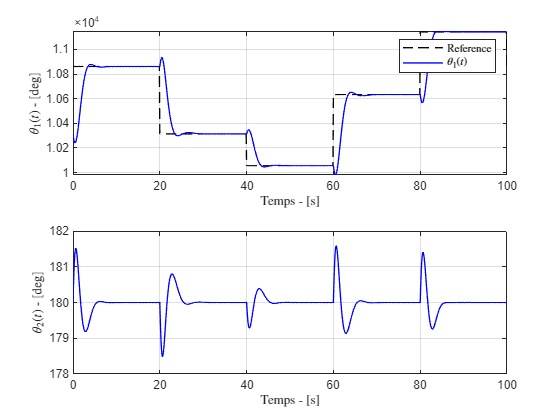

% Définition du vecteur d'état initial (i.e., x[t=0])
x_0 = [pi, 0, pi, 0];

% On utilise le modèle Simulink pour simuler le comportement du double
% pendule
y_out = sim('Modele_pendule_d.slx', 0:0.1:100);

% On affiche le résultat
figure(); 
subplot(2,1,1); grid on; hold on; box on;
plot(y_out.tout, (y_out.results.signals.values(:, 1)*180/pi), '--k', 'LineWidth', 1); 
plot(y_out.tout, (y_out.results.signals.values(:, 2)*180/pi), '-b', 'LineWidth', 1);
xlabel('Temps - [s]', 'Interpreter', 'latex');
ylabel('$\theta_1(t)$ - [deg]', 'Interpreter', 'latex');
h = legend('Reference', '$\theta_1(t)$');
set(h, 'interpreter', 'latex');

subplot(2,1,2); grid on; hold on; box on;
plot(y_out.tout, (y_out.outputs.signals.values(:, 3)*180/pi), '-b', 'LineWidth', 1); 
xlabel('Temps - [s]', 'Interpreter', 'latex');
ylabel('$\theta_2(t)$ - [deg]', 'Interpreter', 'latex');

On peut aussi animer le pendule avec un script de base en Matlab :

% Animation du pendule pour la condition intiale imposée :
f_animationPendule(y_out.tout, y_out.outputs.signals.values, 0.01);

## **4. Conception d'un observateur d'état**

Pour terminer, nous allons maintenant concevoir une observateur d'état. L'idée est de supposer qu'on ne peut mesurer que l'angle du pendule #1. Dans ce cas, il nous faut estimer les autres variables d'état pour pouvoir faire le retour d'état via la méthode LQR. Pour cela, nous allons créer une observateur d'état et faire en sorte que celui-ci soit 2 à 3 fois plus rapide que la boucle de stabilisation réalisé avec LQR.

% Récupération des pôles de la boucle interne (le système + le retour LQR)
poles_lqr = eig(A_lqr);
poles_des = 2*poles_lqr;

% Estimation des gains de l'observateur
L = place(A', [1 0 0 0]', poles_des)' ;

% Création des éléments de l'observateur
A_obs = A; B_obs = B; C_obs = [1 0 0 0];

Simulons le modèle complet pour voir comment le tout fonctionne :

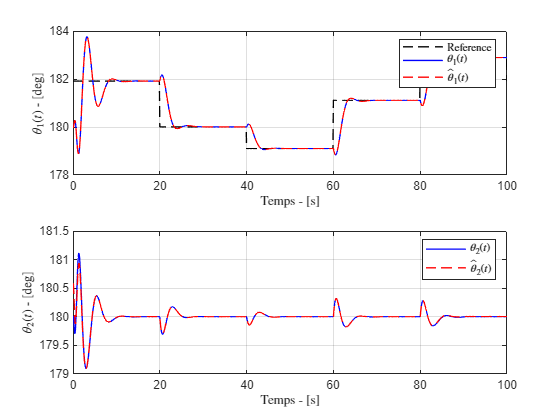

% Définition du vecteur d'état initial (i.e., x[t=0])
x_0 = [pi, 0, pi, 0];

% On utilise le modèle Simulink pour simuler le comportement du double
% pendule
y_out = sim('Modele_pendule_e.slx', 0:0.1:100);

% On affiche le résultat
figure(); 
subplot(2,1,1); grid on; hold on; box on;
plot(y_out.tout, (y_out.results.signals.values(:, 1)*180/pi), '--k', 'LineWidth', 1); 
plot(y_out.tout, (y_out.results.signals.values(:, 2)*180/pi), '-b', 'LineWidth', 1);
plot(y_out.tout, (y_out.outputEstim.signals.values(:, 1)*180/pi), '--r', 'LineWidth', 1);

xlabel('Temps - [s]', 'Interpreter', 'latex');
ylabel('$\theta_1(t)$ - [deg]', 'Interpreter', 'latex');
h = legend('Reference', '$\theta_1(t)$', '$\hat{\theta}_1(t)$');
set(h, 'interpreter', 'latex');

subplot(2,1,2); grid on; hold on; box on;
plot(y_out.tout, (y_out.outputs.signals.values(:, 3)*180/pi), '-b', 'LineWidth', 1); 
plot(y_out.tout, (y_out.outputEstim.signals.values(:, 3)*180/pi), '--r', 'LineWidth', 1);
xlabel('Temps - [s]', 'Interpreter', 'latex');
ylabel('$\theta_2(t)$ - [deg]', 'Interpreter', 'latex');
h = legend('$\theta_2(t)$', '$\hat{\theta}_2(t)$');
set(h, 'interpreter', 'latex');

On peut aussi animer le pendule avec un script de base en Matlab :

% Animation du pendule pour la condition intiale imposée :
f_animationPendule(y_out.tout, y_out.outputs.signals.values, 0.01);